% Limpieza de pantalla
clear all
close all
clc

% TIEMPO DE SIMULACIÓN %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 10;             % Tiempo de simulación en segundos (s)
ts = 0.005;           % Tiempo de muestreo en segundos (s)
t = 0:ts:tf;         % Vector de tiempo
N = length(t);       % Muestras

% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1(1) = 0;           % Posición inicial eje x
y1(1) = 0;           % Posición inicial eje y
phi(1) = 0;          % Orientación inicial del robot 
hx(1) = x1(1);       % Posición del punto de control en X
hy(1) = y1(1);       % Posición del punto de control en Y

%  SELECCIÓN DE TRAYECTORIA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Menú para seleccionar la trayectoria deseada
disp('Seleccione la trayectoria a seguir:');

Seleccione la trayectoria a seguir:


disp('1) x = 2cos(0.2t), y = 2sin(0.4t)');

1) x = 2cos(0.2t), y = 2sin(0.4t)


disp('2) x = t-3sin(t), y = 4-3cos(t)');

2) x = t-3sin(t), y = 4-3cos(t)


disp('3) x = 3cos(t)-cos(3t), y = 4sin(3t)');

3) x = 3cos(t)-cos(3t), y = 4sin(3t)


disp('4) x = cos(t)+(1/2)cos(7t)+(1/3)sin(17t), y = sin(t)+(1/2)sin(7t)+(1/3)cos(17t)');

4) x = cos(t)+(1/2)cos(7t)+(1/3)sin(17t), y = sin(t)+(1/2)sin(7t)+(1/3)cos(17t)


disp('5) x = 17cos(t)+7cos(17+7t), y = 17sin(t)-7sin(17+7t)');

5) x = 17cos(t)+7cos(17+7t), y = 17sin(t)-7sin(17+7t)


disp('6) x = 2cos(t), y = 2sin(t)');

6) x = 2cos(t), y = 2sin(t)


disp('7) x = 5t-4sin(t), y = 5t-4cos(t)');

7) x = 5t-4sin(t), y = 5t-4cos(t)


disp('8) x = 4cos(t)+cos(4t), y = 4sin(t)-sin(4t)');

8) x = 4cos(t)+cos(4t), y = 4sin(t)-sin(4t)


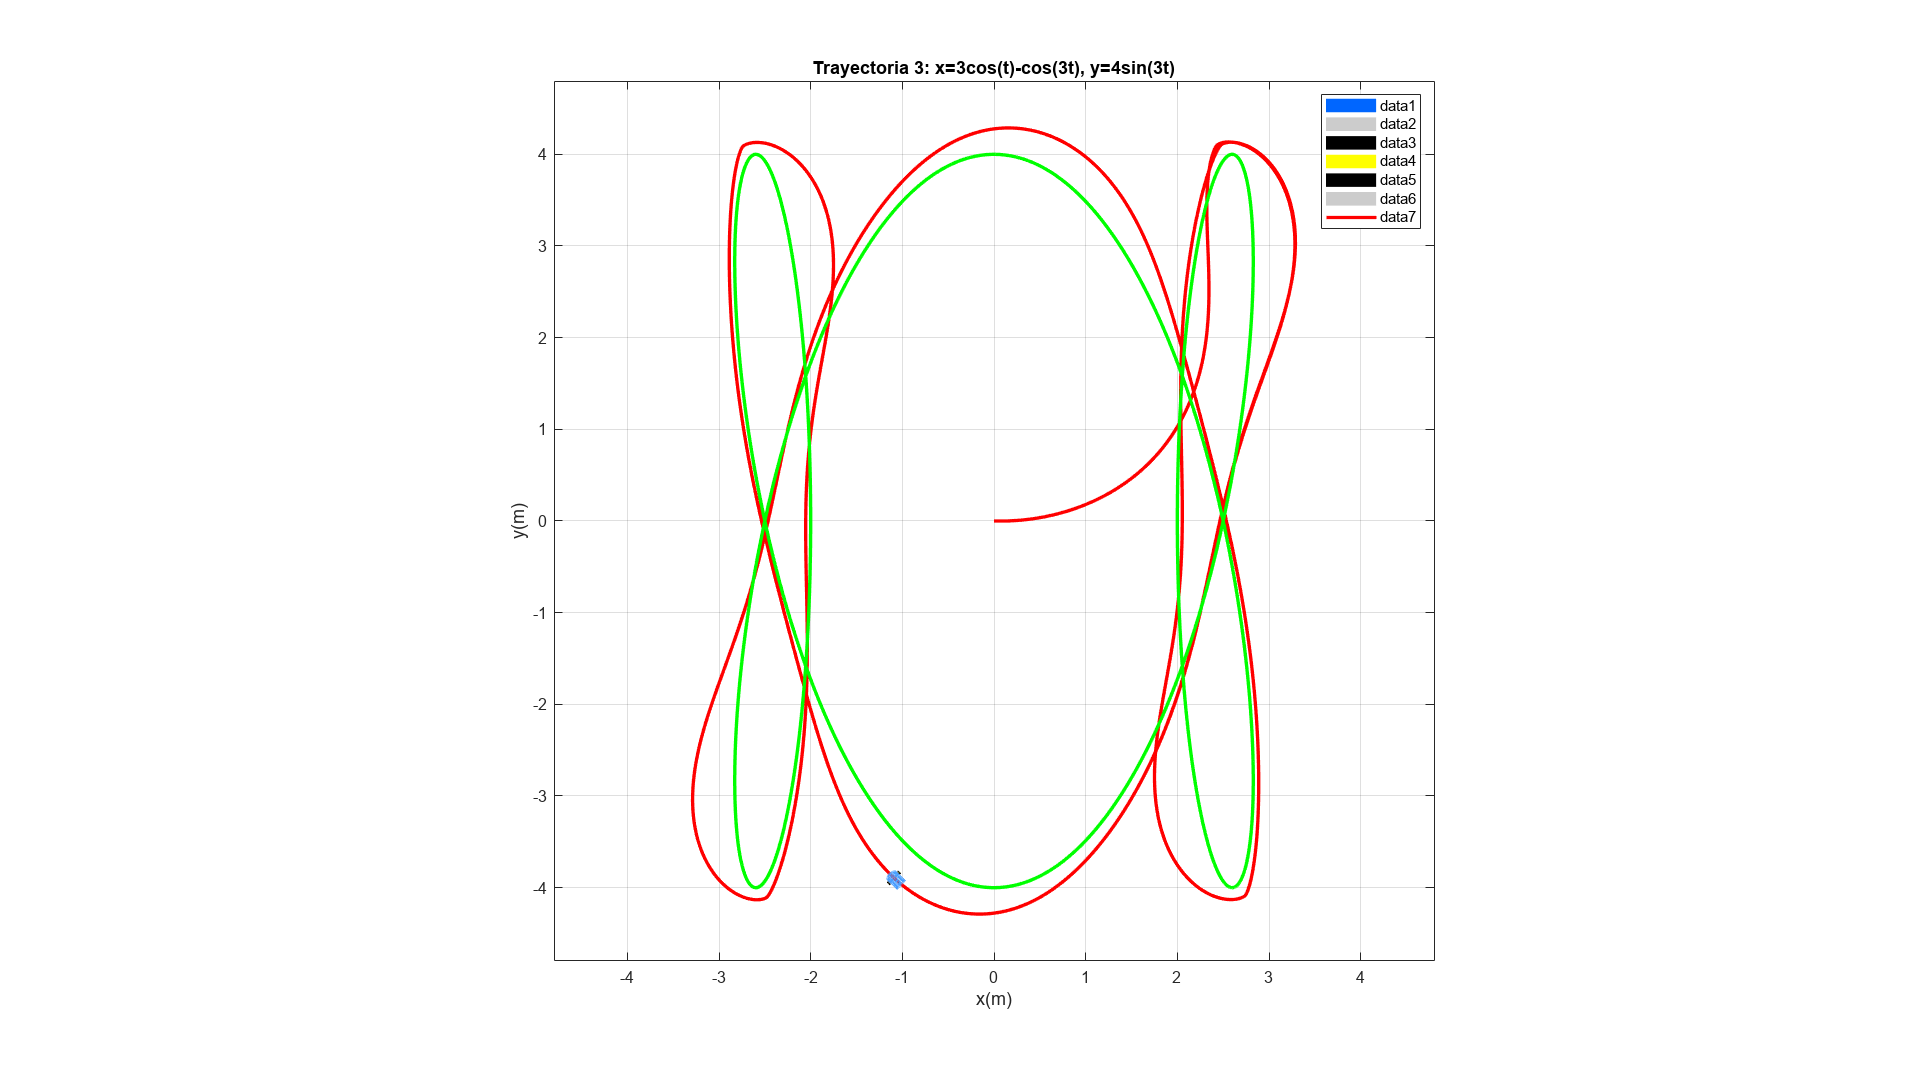


opcion = input('Ingrese el número de la trayectoria (1-8): ');

% Definición de trayectorias según la opción seleccionada
switch opcion
    case 1
        % a) x = 2cos(0.2t), y = 2sin(0.4t)
        hxd = 2*cos(0.2*t);
        hyd = 2*sin(0.4*t);
        hxdp= -4*0.2*sin(0.2*t);
        hydp= 4*0.4*cos(0.4*t);
        %hxdp = -2*0.2*sin(0.2*t);
        %hydp = 2*0.4*cos(0.4*t);
        titulo = 'Trayectoria 1: x=2cos(0.2t), y=2sin(0.4t)';
        
    case 2
        % b) x = t-3sin(t), y = 4-3cos(t)
        hxd = t - 3*sin(t);
        hyd = 4 - 3*cos(t);
        hxdp= -4*0.2*sin(0.2*t);
        hydp= 4*0.4*cos(0.4*t);
        %hxdp = 1 - 3*cos(t);
        %hydp = 3*sin(t);
        titulo = 'Trayectoria 2: x=t-3sin(t), y=4-3cos(t)';
        
    case 3
        % c) x = 3cos(t)-cos(3t), y = 4sin(3t)
        hxd = 3*cos(t) - cos(3*t);
        hyd = 4*sin(3*t);
        hxdp = -3*sin(t) + 3*sin(3*t);
        hydp = 12*cos(3*t);
        titulo = 'Trayectoria 3: x=3cos(t)-cos(3t), y=4sin(3t)';
        
    case 4
        % d) x = cos(t)+(1/2)cos(7t)+(1/3)sin(17t), y = sin(t)+(1/2)sin(7t)+(1/3)cos(17t)
        hxd = cos(t) + (1/2)*cos(7*t) + (1/3)*sin(17*t);
        hyd = sin(t) + (1/2)*sin(7*t) + (1/3)*cos(17*t);
        hxdp = -sin(t) - (7/2)*sin(7*t) + (17/3)*cos(17*t);
        hydp = cos(t) + (7/2)*cos(7*t) - (17/3)*sin(17*t);
        titulo = 'Trayectoria 4: x=cos(t)+(1/2)cos(7t)+(1/3)sin(17t), y=sin(t)+(1/2)sin(7t)+(1/3)cos(17t)';
        
    case 5
        % e) x = 17cos(t)+7cos(17+7t), y = 17sin(t)-7sin(17+7t)
        hxd = 17*cos(t) + 7*cos(17 + 7*t);
        hyd = 17*sin(t) - 7*sin(17 + 7*t);
        hxdp = -17*sin(t) - 49*sin(17 + 7*t);
        hydp = 17*cos(t) - 49*cos(17 + 7*t);
        titulo = 'Trayectoria 5: x=17cos(t)+7cos(17+7t), y=17sin(t)-7sin(17+7t)';
        
    case 6
        % f) x = 2cos(t), y = 2sin(t)
        hxd = 2*cos(t);
        hyd = 2*sin(t);
        hxdp = -2*sin(t);
        hydp = 2*cos(t);
        titulo = 'Trayectoria 6: x=2cos(t), y=2sin(t)';
        
    case 7
        % g) x = 5t-4sin(t), y = 5t-4cos(t)
        hxd = 5*t - 4*sin(t);
        hyd = 5*t - 4*cos(t);
        hxdp = 5 - 4*cos(t);
        hydp = 5 + 4*sin(t);
        titulo = 'Trayectoria 7: x=5t-4sin(t), y=5t-4cos(t)';
        
    case 8
        % h) x = 4cos(t)+cos(4t), y = 4sin(t)-sin(4t)
        hxd = 4*cos(t) + cos(4*t);
        hyd = 4*sin(t) - sin(4*t);
        hxdp = -4*sin(t) - 4*sin(4*t);
        hydp = 4*cos(t) - 4*cos(4*t);
        titulo = 'Trayectoria 8: x=4cos(t)+cos(4t), y=4sin(t)-sin(4t)';
        
    otherwise
        error('Opción no válida. Seleccione un número del 1 al 8.');
end

% CONTROL, BUCLE DE SIMULACIÓN %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
K = [15 0; 0 15];  % Matriz de ganancias (puede ajustarse)

for k = 1:N
    % a) Errores de control
    hxe(k) = hxd(k) - hx(k);
    hye(k) = hyd(k) - hy(k);
    
    % Matriz de error
    he = [hxe(k); hye(k)];
    
    % Magnitud del error de posición
    Error(k) = sqrt(hxe(k)^2 + hye(k)^2);

    % b) Matriz Jacobiana
    J = [cos(phi(k)) -sin(phi(k)); 
         sin(phi(k))  cos(phi(k))];

    % c) Velocidades deseadas
    hdp = [hxdp(k); hydp(k)];

    % d) Ley de Control
    qpRef = pinv(J)*(hdp + K*he);

    v(k) = qpRef(1);   % Velocidad lineal
    w(k) = qpRef(2);   % Velocidad angular

    % 5. APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Integral de la velocidad angular para obtener orientación
    phi(k+1) = phi(k) + w(k)*ts;
    
    % Modelo cinemático
    xp1 = v(k)*cos(phi(k)); 
    yp1 = v(k)*sin(phi(k));
 
    % Integral de la velocidad lineal para obtener posición
    x1(k+1) = x1(k) + ts*xp1;
    y1(k+1) = y1(k) + ts*yp1;

    % Posición del punto de control
    hx(k+1) = x1(k+1); 
    hy(k+1) = y1(k+1);
end

% 6. SIMULACIÓN VIRTUAL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene = figure;
set(scene,'Color','white');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
title(titulo);

% Ajuste automático de los límites de los ejes
margin = 1.2 * max([abs(hxd), abs(hyd)]);
axis([-margin margin -margin margin 0 1]);

% Graficar robot en posición inicial
scale = 1;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;

% Graficar trayectorias
H2 = plot3(hx(1), hy(1), 0, 'r', 'lineWidth', 2);
H3 = plot3(hxd, hyd, zeros(1,N), 'g', 'lineWidth', 2);
legend('Robot', 'Trayectoria Real', 'Trayectoria Deseada');

% Simulación de movimiento
step = 1;
for k = 1:step:N
    delete(H1);    
    delete(H2);
    
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    
    pause(ts);
end


%  GRÁFICAS DE RESULTADOS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph,'position',sizeScreen);

subplot(311)
plot(t, v, 'b', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('m/s')
title('Velocidad Lineal (v)');

subplot(312)
plot(t, w, 'g', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('rad/s')
title('Velocidad Angular (w)');

subplot(313)
plot(t, Error, 'r', 'LineWidth', 2), grid on
xlabel('Tiempo [s]'), ylabel('metros')
title('Error de posición');